# **UE1 USRP B210  Receiver **

## Set OFDM Frame Parameters

clear;

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 512;              % FFT length
OFDMParams.CPLength               = ceil(OFDMParams.FFTLength*0.25);   % Cyclic prefix length
OFDMParams.RB                     = 30;
OFDMParams.NumSubcarriers         = OFDMParams.RB*12;                  % Number of sub-carriers in the band = resourceblock * 12 (must less than FFTlength)
OFDMParams.Subcarrierspacing      = 30e3;              % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = (OFDMParams.FFTLength+OFDMParams.NumSubcarriers)*OFDMParams.Subcarrierspacing*0.5;   % Bandwidth of the channel

% check if NumSubcarriers less than FFTLength
if OFDMParams.NumSubcarriers > OFDMParams.FFTLength
    error('NumSubcarriers: (%d) exceeds FFTLength: (%d), which is not allowed. Please reduce the value of RB.', ...
        OFDMParams.NumSubcarriers, OFDMParams.FFTLength);
end

% Data Parameters
dataParams.modOrder       = 16;   % Data modulation order
dataParams.coderate       = "1/2";   % Code rate
dataParams.numSymPerFrame = 30;   % Number of data symbols per frame
dataParams.numFrames      = 30;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = true;                    % Control to print the output diagnostics at each level of receiver processing
dataParams.printData      = true;                    % Control to print the output decoded data
dataParams.enableConst_measure = true;

## Initialize Receiver Parameters

radioDevice            = "B210";   % Choose radio device for reception
channelmapping         = 1;  % mutichannel or single channel selection
centerFrequency        = 2.5e9;  % Center Frequency
% centerFrequency        = 2.50288e9;
gain                   = 60;  % Set radio gain
gain                   = 40;
save_data              = false;
read_savedData         = false;

read_filename = 'saved_frameData_qam1024.bb';            % read saved received data from specific filename         
save_filename = 'saved_frameData_qam4096.bb';           % save receiving data to specific filename

[sysParam,txParam,transportBlk_bs1,transportBlk_bs2] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
sysParam.enableTimescope = false;
sysParam.enableCFO = true;
sysParam.enableCPE = true;
sysParam.enableChest = true;
sysParam.enableHeaderCRCcheck = true;

if read_savedData
    bbr = comm.BasebandFileReader(read_filename, ...
    SamplesPerFrame=sysParam.txWaveformSize);
end
ofdmRx = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain,channelmapping);

Checking radio connections...


[radio,spectrumAnalyze,constDiag, timesink, constellation_measure] = helperGetRadioRxObj(ofdmRx);
% timesink = 1;
constDiag.ShowTrajectory = false;

## Execute Receiver Loop

#### Synchronization

#### Frequency Offset Estimation and Correction

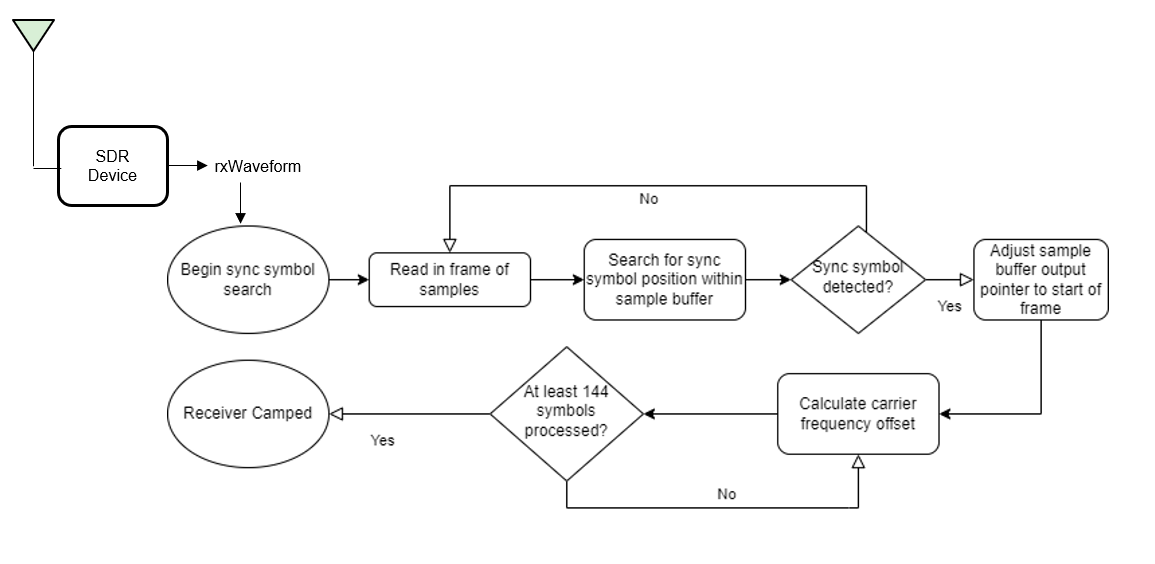

### Receiver Processing

#### Channel Estimation and Equalization

#### Header Decoding

#### Data Decoding

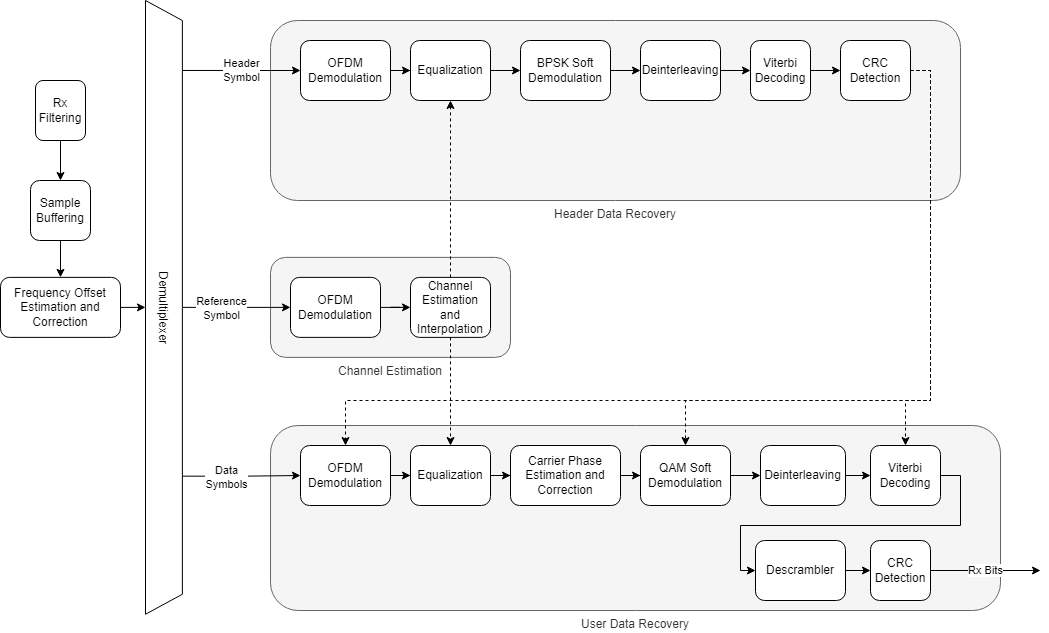

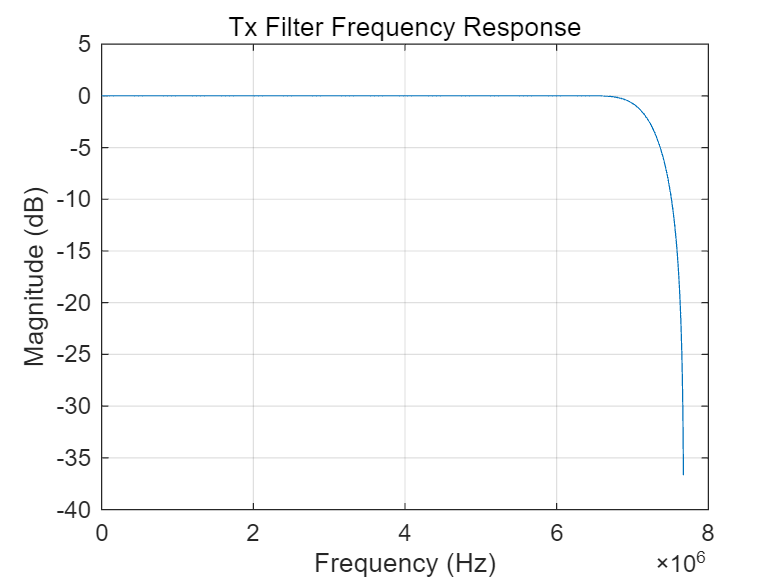

% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;


errorRate_bs1 = comm.ErrorRate();
errorRate_bs2 = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);

..............................

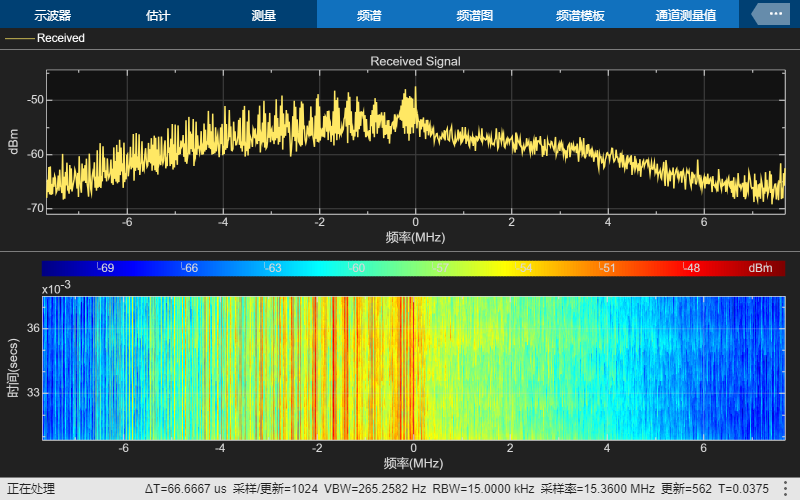

BER_bs1 = zeros(1,dataParams.numFrames);
BER_bs2 = zeros(1,dataParams.numFrames);
data_collec = [];
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    if read_savedData
        rxWaveform = bbr();
        overflow = 0;
    else
        [rxWaveform, ~, overflow] = radio();
    end
    
    if save_data
        data_collec = [data_collec;rxWaveform];
    end
    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj, timesink);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals_bs1 = errorRate_bs1(...
                transportBlk_bs1((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER_bs1(frameNum) = berVals_bs1(1);

            berVals_bs2 = errorRate_bs2(...
                transportBlk_bs2((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER_bs2(frameNum) = berVals_bs2(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data upto last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                complex(rxDiagnostics.rxConstellationData(:)));
        end

        rmsEVM_header = 0; 
        rmsEVM_data = 0; 
        merdb_header = 0;
        merdb_data = 0;

        if isConnected && dataParams.enableConst_measure
            rmsEVM_header = constellation_measure.evm_header(complex(rxDiagnostics.rxConstellationHeader(:))); 
            rmsEVM_data = constellation_measure.evm_data(complex(rxDiagnostics.rxConstellationData(:))); 
            merdb_header = constellation_measure.mer_header(complex(rxDiagnostics.rxConstellationHeader(:)));
            merdb_data = constellation_measure.mer_data(complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
end

% Display the mean BER value across all frames
fprintf(['Simulation complete!\n' ...
    'BS1 massage Average BER = %d \n' ...
    'BS2 massage Average BER = %d \n' ...
    '-------measurement-------\n' ...
    'Header rms EVM(%%): %.3f %% \n' ...
    'Data rms EVM(%%): %.3f %% \n' ...
    'Header MER(dB): %.3f dB \n' ...
    'Data MER(dB): %.3f dB'],mean(BER_bs1),mean(BER_bs2),rmsEVM_header, rmsEVM_data, merdb_header, merdb_data)

Simulation complete!
BS1 massage Average BER = 0 
BS2 massage Average BER = 0 
-------measurement-------
Header rms EVM(%): 0.000 % 
Data rms EVM(%): 0.000 % 
Header MER(dB): 0.000 dB 
Data MER(dB): 0.000 dB

% fprintf('-------measurement-------')
% fprintf('Header rms EVM(%%): %.3f %%', rmsEVM_header)
% fprintf('Data rms EVM(%%): %.3f %%', rmsEVM_data)
% fprintf('Header MER(dB): %.3f dB', merdb_header)
% fprintf('Data MER(dB): %.3f dB', merdb_data)
if save_data
    bbw = comm.BasebandFileWriter(save_filename,SampleRate=sampleRate,CenterFrequency=centerFrequency);
    bbw(data_collec);
    info(bbw)
    release(bbw)
end
if read_savedData
    release(bbr)
end
release(radio);